# RFID Antenna Design

This example shows how to design a commercial RFID antenna operating at 915 MHz. This example uses Partial Differential Equation Toolbox™ to draw and mesh the planar structure. The meshed structure is then imported into Antenna Toolbox™ and analyzed for its electromagnetic properties.

## RFID Antenna

Below is a commercially available RFID antenna. These tags are typically used on boxes for inventory tracking. The main requirement for these tags is the low manufacturing cost and a narrow bandwidth. The antenna below has an overall dimension of 22 mm-by-22 mm.

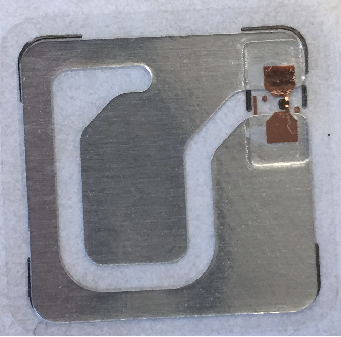

**Fig.1: RFID antenna tag**

## Draw Antenna Geometry

Use the `pdeModeler` app in Partial Differential Equation Toolbox to draw the antenna geometry. The pdeModeler app provides a graphical user interface to draw and mesh a 2-D geometry. Run pdeModeler command without arguments to start the application. The figure below is the snapshot of the pdeModeler with a basic layout of the antenna. Use rectangle R1 to create the 22 mm square. Create various slots in the structure using rectangles R2 to R5 as shown below. Connect the rectangle R5 to R6 using a polygon shape. Use similar idea to connect rectangle  R2 with R3.

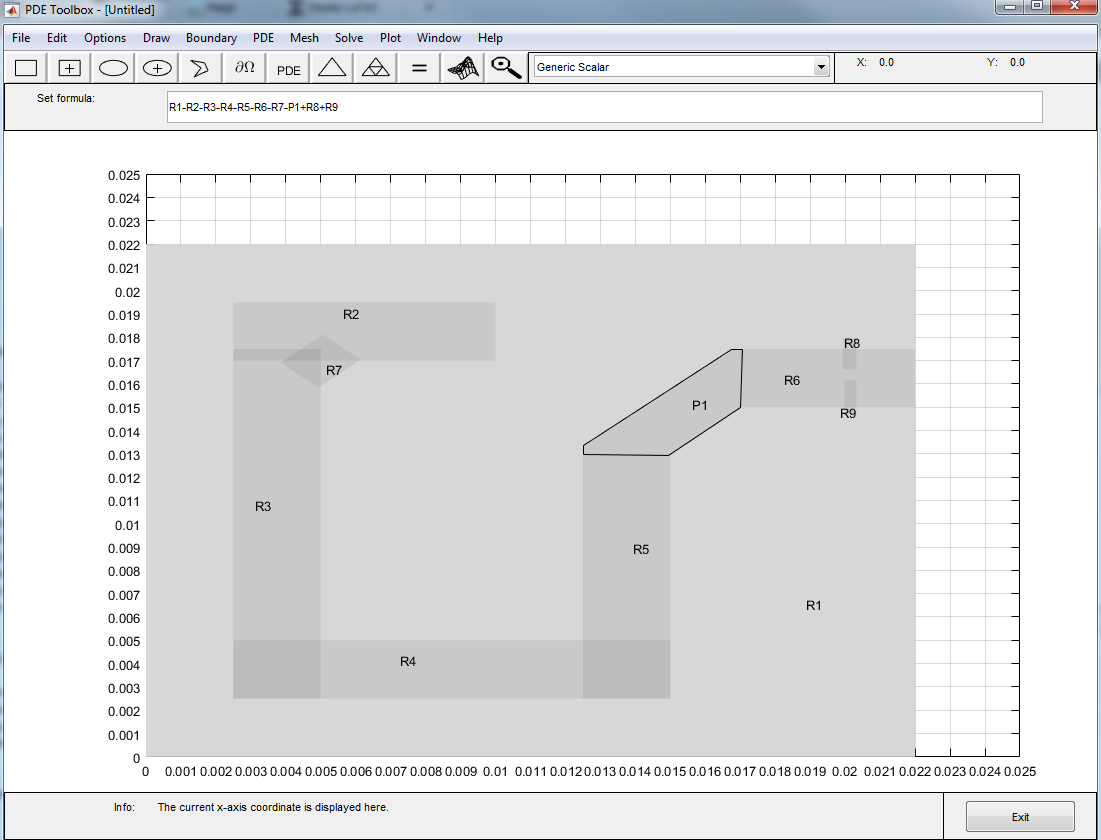

**Fig.2. Layout of the antenna geometry**

Once the desired antenna geometry is set up, perform Boolean operations on the various shapes. Subtract the rectangles R2 to R7 from the rectangle R1 to create the slots. Add the two rectangles R8 and R9 so that a feed can be attached between them. Perform the Boolean operation in the Set formula tab.

## Mesh Antenna Geometry

Once the Set formula tab is filled with the correct Boolean operation, press the triangle button, to mesh the structure. Maximum edge length in the mesh can be modified by setting the Max edge size value under **Mesh->Parameters **tab. Generate the mesh with a maximum edge length of 2 mm.

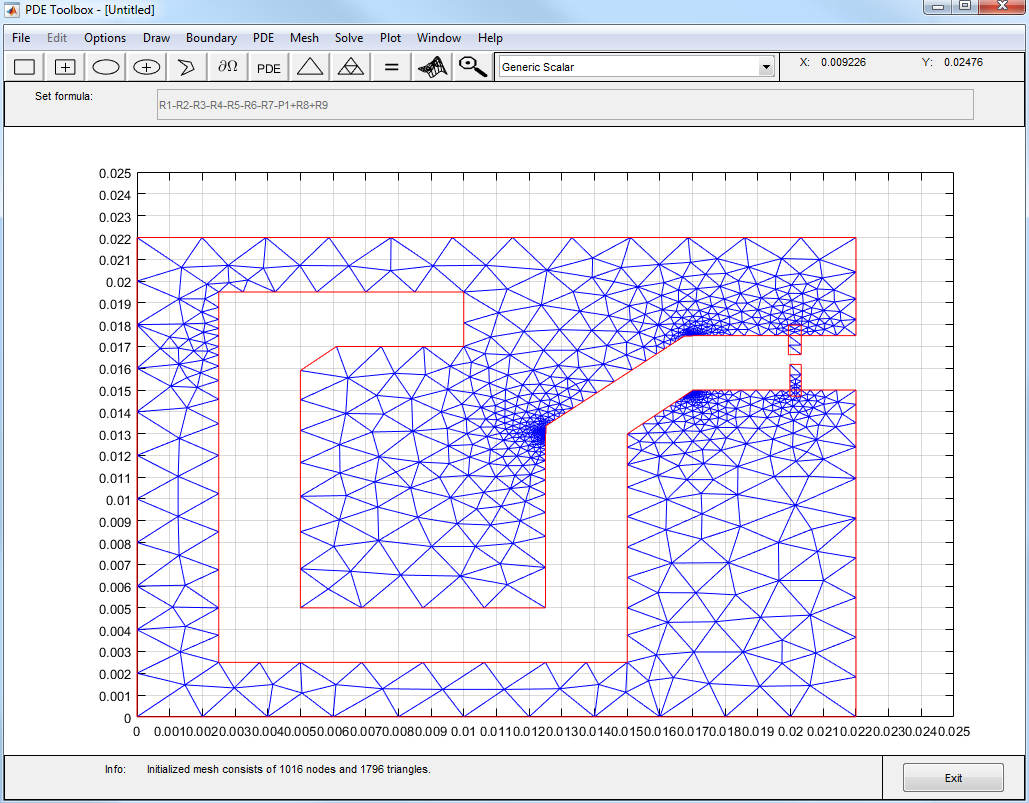

**Fig.3. Meshed antenna geometry**

Export the generated mesh to the MATLAB workspace by selecting the **Mesh-> Export Mesh** option. The p (Points), e (boundary edges) and t (triangles) are exported to the workspace. Save the exported data in the `'RFIDtag.mat'` file. Save the complete antenna geometry in the `'RFIDtag.m'` file.

## Create Custom Antenna

Use the [customAntennaMesh](docid:antenna_ref#bvd8l0r-1) object from the Antenna Toolbox to import the custom planar mesh from the saved MAT file. To convert this mesh to an antenna, a feed needs to be defined. This determines where the antenna is excited.

load RFIDtag
ant = customAntennaMesh(p,t);

Create the feed by using the `createFeed` function GUI or by specifying the two points across which the feed is defined. This section shows both the approaches. Calling [createFeed](docid:antenna_ref#bux2yxy-1) with just the antenna as the input parameter opens the feed creating GUI.

Pick a gap in the metal to feed the antenna. The interactive figure allows you to select two triangles across the gap. Click the **Pick** button which provides a cross hair to pick the two triangles. The figure below shows the way to select the first triangle. Bring the cross hair over the triangle as shown below and press the left mouse button.

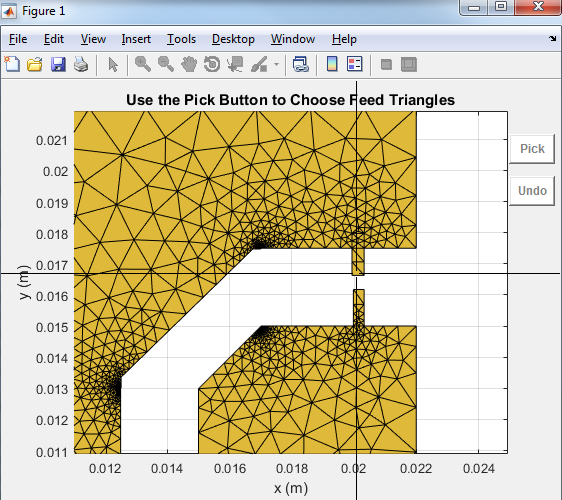

Repeat the process for the second triangle across the gap. Once the two feed triangles are selected the figure updates to show the feed with green triangles as shown below. The red dot shows the feeding edge. To change the feed location, click the **Undo** button and start again.

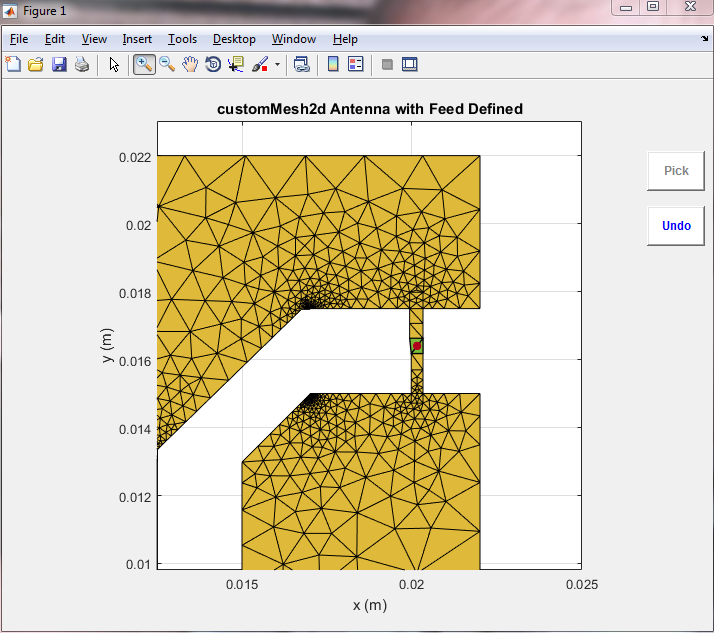

The other way to create the feed is by specifying the two points between which the feed needs to be created as shown below. Use the [show](docid:antenna_ref#bukkic2-1) function to visualize the antenna.

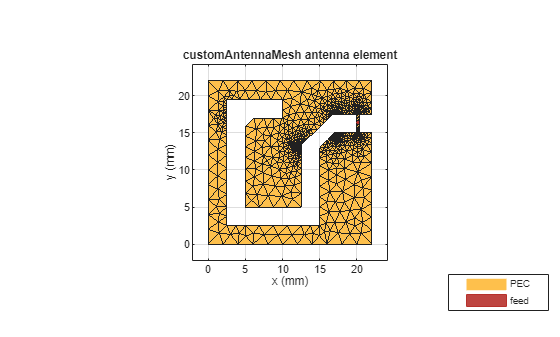

createFeed(ant,[0.0201 0.0168],[0.0201 0.0161]);
show(ant)
view(2);

## Calculate Impedance of RFID Antenna

Use the `impedance` function to calculate the impedance of the antenna at 915 MHz.

z = impedance(ant,915e6)

z = 7.0565e-01 + 2.9162e+02i

The impedance values above indicate that the antenna is highly inductive with a small resistance value. This is typical for RFID tags. A matching network at 915MHz need to be designed for successful operation of the tag.

More information on designing a matching network can be obtained in the following demo: [Impedance Matching of a Non-resonant(Small) Monopole](docid:antenna_ug#example-ex69883049)

## Plot Radiation Pattern of RFID Antenna

The directivity of the RFID antenna is shown below. The tag has a null at the zenith but good coverage in the *xy*-plane and a maximum value of about 1.5dBi. This shows that the antenna is operational over a short distance from the reader, which is a requirement for an RFID tag.

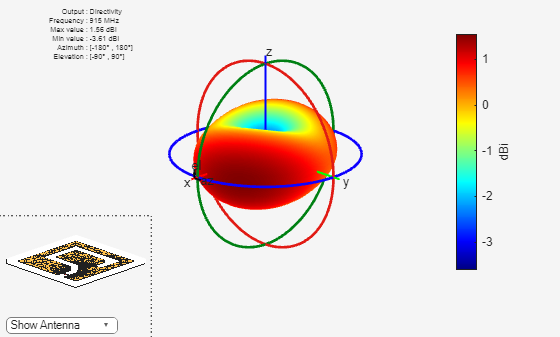

pattern(ant,915e6);

*Copyright 2015-24 The MathWorks, Inc.*